%% Task A : Calculate Maximum Height of Rocket Trajectory
% This script determines the maximum height of the rocket trajectory.
% Includes error estimation by comparing results with different step sizes.
% Implements quadratic interpolation from scratch to refine maximum height.

%% Clear environment
clear all
close all
clc

%% Define initial parameters
% Initial conditions
v_init = 21;             % Initial velocity magnitude (m/s)
theta_init = 81;         % Initial angle (degrees)
theta = deg2rad(theta_init); % Convert to radians

% Simulation parameters
t_start = 0;             % Start time (s)
t_burn = 0.08;           % Burn time end (s)
t_end = 4;               % Simulation end time (s)
F = 1;                   % Force during burn time (N)

% Step sizes for error analysis
h_values = [0.01, 0.005, 0.0025]; % Time steps for different precision levels
n_steps = length(h_values);

%% Part 1: Study the error at the last point with different step sizes
% Initialize arrays to store results
max_heights = zeros(n_steps, 1);
last_heights = zeros(n_steps, 1);
x_at_max = zeros(n_steps, 1);
idx_max_values = zeros(n_steps, 1);

fprintf('=== Part 1: Error at Last Point ===\n');

=== Part 1: Error at Last Point ===


fprintf('Running simulations with different step sizes...\n');

Running simulations with different step sizes...



% Store trajectories for later visualization
all_trajectories = cell(n_steps, 1);
all_times = cell(n_steps, 1);
k1=0;
k2 = 0;
k3=0;
k4=0;
k_last = zeros(n_steps, 4); % Each row: [k1_end, k2_end, k3_end, k4_end]

% Run simulations with different step sizes
for i = 1:n_steps
    h = h_values(i);
    % Simulate rocket trajectory
    [z, t] = simulate_rocket(t_start, t_burn, t_end, h, F, v_init, theta);
    %[z, t, k12, k22, k32, k42] = simulate_rocket_with_k(t_start, t_burn, t_end, h, F, v_init, theta);


    % Store just the last value for analysis
    % Store only the last value of each k for analysis
    %k_last(i, :) = [k12(end), k22(end), k32(end), k42(end)];

    % Store trajectory
    all_trajectories{i} = z;
    all_times{i} = t;
    
    % Find raw maximum height (still needed for visualization)
    [max_height_raw, idx_max] = max(z(2,:));
    max_heights(i) = max_height_raw;
    x_at_max(i) = z(1, idx_max);
    idx_max_values(i) = idx_max;
    fprintf("idx_max: %.10f", idx_max);
    % Get height at last point
    last_heights(i) = z(2, end);
    
    fprintf('Step size h = %.6f: Last point height = %.15f m at x = %.6f m\n', ...
            h, last_heights(i), z(1, end));
end

idx_max: 175.0000000000

Step size h = 0.010000: Last point height = -4.474703756766275 m at x = 9.238636 m


idx_max: 348.0000000000

Step size h = 0.005000: Last point height = -4.474703757471030 m at x = 9.238636 m


idx_max: 695.0000000000

Step size h = 0.002500: Last point height = -4.474703757515183 m at x = 9.238636 m



fprintf('\nLast values of k1–k4 for each step size:\n');


Last values of k1–k4 for each step size:


disp(array2table(k_last, 'VariableNames', {'k1', 'k2', 'k3', 'k4'}));

    k1    k2    k3    k4
    __    __    __    __

    0     0     0     0 
    0     0     0     0 
    0     0     0     0 




% Compute differences
k1_minus_k2 = k_last(:, 1) - k_last(:, 2);
k3_minus_k4 = k_last(:, 3) - k_last(:, 4);

% Print the differences
fprintf('\nDifferences between k1 and k2:\n');


Differences between k1 and k2:


disp(k1_minus_k2);

     0
     0
     0




fprintf('\nDifferences between k3 and k4:\n');


Differences between k3 and k4:


disp(k3_minus_k4);

     0
     0
     0





% Calculate differences in last height values between consecutive step sizes
height_diffs = zeros(n_steps-1, 1);
for i = 1:n_steps-1
    height_diffs(i) = abs(last_heights(i) - last_heights(i+1));
    fprintf('diff%d = abs(last_height_%d - last_height_%d) = %.15f m\n', ...
            i, i, i+1, height_diffs(i));
end

diff1 = abs(last_height_1 - last_height_2) = 0.000000000704754 m
diff2 = abs(last_height_2 - last_height_3) = 0.000000000044153 m



% Estimate convergence rate
if n_steps >= 3
    % Using the two finest discretizations
    ratio = height_diffs(1) / height_diffs(2);
    p_est = -log(ratio) / log(2); % Assuming step size ratio of 2
    
    fprintf("Estimated convergence rate: %.5f", ratio)
    fprintf('\nEstimated convergence rate based on last point differences: p ≈ %.2f\n', p_est);
    fprintf('Estimated error in finest solution: %.6e m\n', height_diffs(end));
end

Estimated convergence rate: 15.96160


Estimated convergence rate based on last point differences: p ≈ -4.00


Estimated error in finest solution: 4.415313e-11 m






%% Part 2: Study the interpolation error with different step sizes for interpolation
fprintf('\n=== Part 2: Error in Interpolated Maximum Height ===\n');


=== Part 2: Error in Interpolated Maximum Height ===



% We'll use the finest trajectory for this analysis
z_finest = all_trajectories{end};
t_finest = all_times{end};
[~, idx_max_finest] = max(z_finest(2,:));
finest_x_at_max = z_finest(1, idx_max_finest);

% Different step sizes for selecting adjacent points (in terms of indices)
step_sizes = [1, 2, 4];
n_interp_steps = length(step_sizes);

% Initialize arrays to store interpolation results
max_heights_interp = zeros(n_interp_steps, 1);
x_at_max_interp = zeros(n_interp_steps, 1);
interp_diff = nan(n_interp_steps, 1); % First difference will be NaN

for i = 1:n_interp_steps
    step = step_sizes(i);
    
    % Find interpolated maximum height using quadratic interpolation
    [max_height_interp, x_interp, coefs] = find_max_height_interp(z_finest, idx_max_finest, step);
    
    % Store results
    max_heights_interp(i) = max_height_interp;
    x_at_max_interp(i) = x_interp;
    
    fprintf('Interpolation step %d: Max height = %.15f m at x = %.15f m\n', ...
            step, max_heights_interp(i), x_at_max_interp(i));
end

Interpolation step 1: Max height = 16.888462550945206 m at x = 4.743915377631542 m
Interpolation step 2: Max height = 16.888462550734008 m at x = 4.743914572317966 m
Interpolation step 4: Max height = 16.888462549900499 m at x = 4.743911350804146 m



% Calculate differences between consecutive interpolation steps
for i = 2:n_interp_steps
    interp_diff(i) = abs(max_heights_interp(i) - max_heights_interp(i-1));
end

% Print differences
fprintf('\nDifferences between consecutive interpolation steps:\n');


Differences between consecutive interpolation steps:


for i = 1:n_interp_steps
    if isnan(interp_diff(i))
        fprintf('interp_diff%d = NaN\n', i-1);
    else
        fprintf('interp_diff%d = abs(interp_height_%d - interp_height_%d) = %.8e m\n', ...
                i-1, i-1, i, interp_diff(i));
    end
end

interp_diff0 = NaN


interp_diff1 = abs(interp_height_1 - interp_height_2) = 2.11198170e-10 m
interp_diff2 = abs(interp_height_2 - interp_height_3) = 8.33509262e-10 m



%% Part 3: Combine Results and Estimate Final Error
fprintf('\n=== Part 3: Final Results ===\n');


=== Part 3: Final Results ===



% Best end-point estimate (finest grid)
best_end_pt = last_heights(end);
end_pt_error = height_diffs(end);

% Best interpolated estimate (smallest interpolation step)
best_interp = max_heights_interp(1);
interp_error = interp_diff(2);

% Combined error (RSS - Root Sum Square)
combined_error = sqrt(end_pt_error^2 + interp_error^2);

fprintf('Best height at last point: %.15f ± %.5e m\n', best_end_pt, end_pt_error);

Best height at last point: -4.474703757515183 ± 4.41531e-11 m


fprintf('Best interpolated maximum height: %.15f ± %.5e m\n', best_interp, interp_error);

Best interpolated maximum height: 16.888462550945206 ± 2.11198e-10 m


fprintf('Final result:\n    Max height = %.15f ± %.5e m\n', best_interp, combined_error);

Final result:
    Max height = 16.888462550945206 ± 2.15764e-10 m


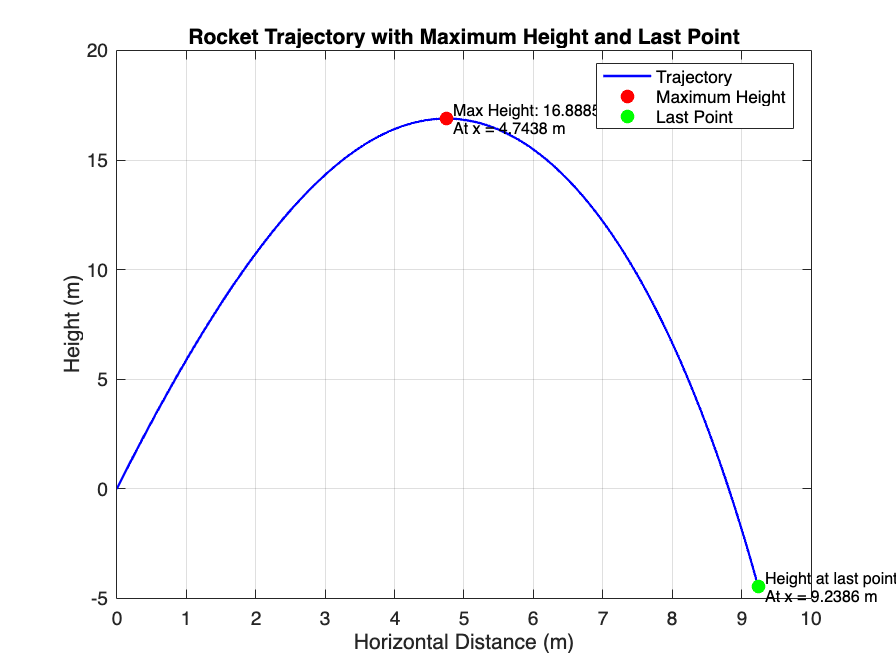


%% Visualize results
% 1. Plot the trajectory for raw finest step size
figure(1);
finest_idx = length(h_values); % Index of the finest step size
trajectory = all_trajectories{finest_idx};
time = all_times{finest_idx};
idx_max = idx_max_values(finest_idx);

% Plot the full trajectory
plot(trajectory(1,:), trajectory(2,:), 'b-', 'LineWidth', 1.5);
hold on;

% Mark the maximum point
plot(trajectory(1,idx_max), trajectory(2,idx_max), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

% Mark the last point 
plot(trajectory(1,end), trajectory(2,end), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

% Add a text label for the maximum point
text(trajectory(1,idx_max)+0.1, trajectory(2,idx_max), ...
    sprintf('Max Height: %.4f m\nAt x = %.4f m', max_heights(finest_idx), x_at_max(finest_idx)), ...
    'FontSize', 10);

% Add a text label for the last point
text(trajectory(1,end)+0.1, trajectory(2,end), ...
    sprintf('Height at last point: %.4f m\nAt x = %.4f m', last_heights(finest_idx), trajectory(1,end)), ...
    'FontSize', 10);

% Add grid, labels, and title
grid on;
xlabel('Horizontal Distance (m)');
ylabel('Height (m)');
title('Rocket Trajectory with Maximum Height and Last Point');
set(gca, 'FontSize', 12);
legend('Trajectory', 'Maximum Height', 'Last Point', 'Location', 'best');
hold off;

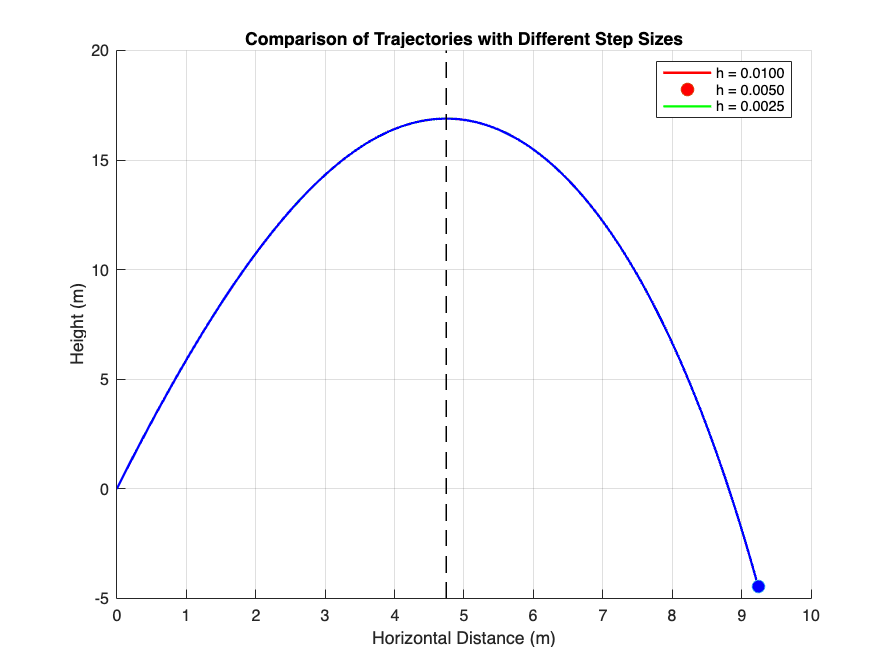


% 2. Visualize different step size solutions
figure(2);
colors = {'r-', 'g-', 'b-'};
legends = cell(n_steps, 1);

hold on;
for i = 1:n_steps
    trajectory = all_trajectories{i};
    
    % Plot the trajectory
    plot(trajectory(1,:), trajectory(2,:), colors{i}, 'LineWidth', 1.5);
    
    % Mark the height at the last point
    last_idx_traj = size(trajectory, 2);
    plot(trajectory(1,last_idx_traj), trajectory(2,last_idx_traj), 'o', 'MarkerSize', 8, 'MarkerFaceColor', colors{i}(1));
    
    legends{i} = sprintf('h = %.4f', h_values(i));
end

% Add vertical line at max height position
yLimits = ylim;
plot([finest_x_at_max, finest_x_at_max], yLimits, 'k--', 'LineWidth', 1);

% Add labels and title
xlabel('Horizontal Distance (m)');
ylabel('Height (m)');
title('Comparison of Trajectories with Different Step Sizes');
grid on;
legend(legends, 'Location', 'best');
hold off;

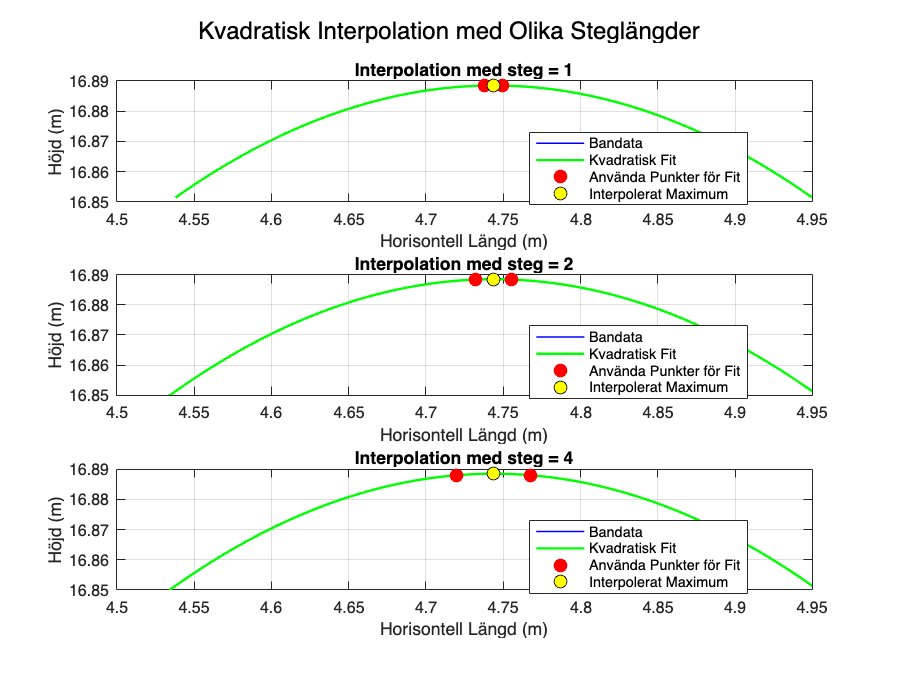


% 3. Visualize the interpolation with different step sizes
figure(3);
z_finest = all_trajectories{end};
[~, idx_max_finest] = max(z_finest(2,:));

% Create 3 subplots, one for each interpolation step size
for i = 1:length(step_sizes)
    step = step_sizes(i);
    
    % Determine the indices of points used for interpolation
    if idx_max_finest > step && idx_max_finest < length(z_finest(2,:)) - step
        idx_range = [idx_max_finest-step, idx_max_finest, idx_max_finest+step];
    else
        if idx_max_finest <= step
            idx_range = [1, 1+step, 1+2*step];
        else
            idx_range = [length(z_finest(2,:))-2*step, length(z_finest(2,:))-step, length(z_finest(2,:))];
        end
    end
    
    % Create the subplot
    subplot(3, 1, i);
    
    % Get points for interpolation
    x_vals = z_finest(1, idx_range);
    y_vals = z_finest(2, idx_range);
    
    % Fit a quadratic polynomial
    A = [x_vals(1)^2, x_vals(1), 1;
         x_vals(2)^2, x_vals(2), 1;
         x_vals(3)^2, x_vals(3), 1];
    
    b = y_vals(:);
    coeffs = A \ b;
    a = coeffs(1);
    b = coeffs(2);
    c = coeffs(3);
    
    % Calculate the interpolated maximum
    max_x = -b / (2*a);
    max_height = a*max_x^2 + b*max_x + c;
    
    % Define a fine grid for plotting the parabola
    x_fine = linspace(min(x_vals)-0.2, max(x_vals)+0.2, 100);
    y_fine = a*x_fine.^2 + b*x_fine + c;
    
    % Plot nearby trajectory points
    plot_range = max(idx_range(1)-10, 1):min(idx_range(3)+10, length(z_finest(1,:)));
    plot(z_finest(1, plot_range), z_finest(2, plot_range), 'b-', 'LineWidth', 1);
    hold on;
    
    % Plot the quadratic interpolation
    plot(x_fine, y_fine, 'g-', 'LineWidth', 1.5);
    
    % Mark the points used for interpolation
    plot(x_vals, y_vals, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    
    % Mark the interpolated maximum
    plot(max_x, max_height, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'y');
    
    % Add labels and title
    xlabel('Horisontell Längd (m)');
    ylabel('Höjd (m)');
    title(sprintf('Interpolation med steg = %d', step));
    
    % Add legend
    legend('Bandata', 'Kvadratisk Fit', 'Använda Punkter för Fit', 'Interpolerat Maximum', ...
           'Location', 'best');
    
    % Add text with interpolation results
    text(max(xlim)*0.6, max(ylim)*0.9, ...
        sprintf('Max Höjd: %.6f m\nvid x = %.4f m', max_height, max_x), ...
        'FontSize', 8, 'BackgroundColor', [1 1 0.8]);
    
    grid on;
    hold off;
    
    % Keep the same dimensions for all subplots
    if i == 1
        xlim_val = xlim;
        ylim_val = ylim;
    else
        xlim(xlim_val);
        ylim(ylim_val);
    end
end

% Adjust the layout
sgtitle('Kvadratisk Interpolation med Olika Steglängder');
set(gcf, 'Position', [100, 100, 800, 600]);



%% Helper Functions


function [z, t] = simulate_rocket(t_start, t_burn, t_end, h, F, v_init, theta)
    % Initial conditions
    x0 = 0;
    y0 = 0;
    [vx0, vy0] = decompose_velocity(v_init, theta);
    
    % Phase 1: With thrust (t_start to t_burn)
    [z1, t1] = runge_kutta(t_start, t_burn, h, F, x0, y0, vx0, vy0, theta);
    
    % Phase 2: No thrust (t_burn to t_end)
    [z2, t2] = runge_kutta(t_burn, t_end, h, 0, z1(1,end), z1(2,end), z1(3,end), z1(4,end), theta);
    
    % Combine results
    z = [z1, z2(:,2:end)];
    t = [t1, t2(2:end)];
end

function [z, t, k1, k2, k3, k4] = simulate_rocket_with_k(t_start, t_burn, t_end, h, F, v_init, theta)
    % Initial conditions
    x0 = 0;
    y0 = 0;
    [vx0, vy0] = decompose_velocity(v_init, theta);
    
    % Phase 1: With thrust (t_start to t_burn)
    [z1, t1] = runge_kutta(t_start, t_burn, h, F, x0, y0, vx0, vy0, theta);
    
    % Phase 2: No thrust (t_burn to t_end)
    [z2, t2, k11, k22, k33, k44] = runge_kutta_with_k(t_burn, t_end, h, 0, z1(1,end), z1(2,end), z1(3,end), z1(4,end), theta);
    
    k1=k11;
    k2=k22;
    k3=k33;
    k4=k44;


    % Combine results
    z = [z1, z2(:,2:end)];
    t = [t1, t2(2:end)];
end

function [z, t] = runge_kutta(t_start, t_end, h, F, x0, y0, vx0, vy0, theta)
    % Generate time values
    t = t_start:h:t_end;
    N = length(t);
    
    % Initialize solution matrix [x, y, vx, vy]
    z = zeros(4, N);
    z(:, 1) = [x0; y0; vx0; vy0];
    
    % Runge-Kutta integration
    for i = 1:N-1
        t_current = t(i);
        z_current = z(:, i);
        
        % Four steps of RK4 method
        k1 = rocket_ode(t_current, z_current, F, theta);
        k2 = rocket_ode(t_current + h/2, z_current + (h/2)*k1, F, theta);
        k3 = rocket_ode(t_current + h/2, z_current + (h/2)*k2, F, theta);
        k4 = rocket_ode(t_current + h, z_current + h*k3, F, theta);
        
        % Update solution
        z(:, i+1) = z_current + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
    end

end

function [z, t, k1, k2, k3, k4] = runge_kutta_with_k(t_start, t_end, h, F, x0, y0, vx0, vy0, theta)
    % Generate time values
    t = t_start:h:t_end;
    N = length(t);
    
    % Initialize solution matrix [x, y, vx, vy]
    z = zeros(4, N);
    z(:, 1) = [x0; y0; vx0; vy0];
    
    % Runge-Kutta integration
    for i = 1:N-1
        t_current = t(i);
        z_current = z(:, i);
        
        % Four steps of RK4 method
        k1 = rocket_ode(t_current, z_current, F, theta);
        k2 = rocket_ode(t_current + h/2, z_current + (h/2)*k1, F, theta);
        k3 = rocket_ode(t_current + h/2, z_current + (h/2)*k2, F, theta);
        k4 = rocket_ode(t_current + h, z_current + h*k3, F, theta);
        
        % Update solution
        z(:, i+1) = z_current + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
    end


end

function dzdt = rocket_ode(t, z, F_val, theta_init)
    % Extract state variables
    x = z(1);      % Position x
    y = z(2);      % Position y
    vx = z(3);     % Velocity x
    vy = z(4);     % Velocity y
    
    % Physical parameters
    g = 9.82;      % Gravity (m/s²)
    m0 = 0.05;     % Initial mass (kg)
    k_x = 0.001;   % Air resistance coefficient x
    k_y = 0.001;   % Air resistance coefficient y
    k = 0.08;      % Mass flow rate (kg/s)
    
    % Calculate current mass
    if t <= 0.08
        m = m0 - k*t;
    else
        m = m0 - k*0.08;
    end
    
    % Calculate thrust force
    if t <= 0.08
        F = F_val;
    else
        F = 0;
    end
    
    % Calculate angle
    if t <= 0
        phi = theta_init;
    else
        phi = atan2(vy, vx);  % Using atan2 for correct quadrant
    end
    
    % Calculate speed
    V = sqrt(vx^2 + vy^2);
    
    % Differential equations
    dzdt = zeros(4, 1);
    dzdt(1) = vx;
    dzdt(2) = vy;
    dzdt(3) = (F*cos(phi) - k_x*vx*V)/m;
    dzdt(4) = (F*sin(phi) - k_y*vy*V)/m - g;
end

function [vx, vy] = decompose_velocity(v, theta)
    vx = v*cos(theta);
    vy = v*sin(theta);
end

function [max_height, max_x, coeffs] = find_max_height_interp(z, idx_max, step)
    % Find maximum height using quadratic interpolation
    % with specified step size for selecting adjacent points
    y_pos = z(2,:);
    x_pos = z(1,:);
    
    % Determine interpolation points based on step size
    if idx_max > step && idx_max < length(y_pos) - step
        idx_range = [idx_max-step, idx_max, idx_max+step];
    else
        if idx_max <= step
            idx_range = [1, 1+step, 1+2*step];
        else  % idx_max is near the end
            idx_range = [length(y_pos)-2*step, length(y_pos)-step, length(y_pos)];
        end
    end
    
    % Get points for interpolation
    x_vals = x_pos(idx_range);
    y_vals = y_pos(idx_range);
    
    % Perform quadratic interpolation to find maximum
    % Set up the matrix equation for polynomial coefficients
    A = [x_vals(1)^2, x_vals(1), 1;
         x_vals(2)^2, x_vals(2), 1;
         x_vals(3)^2, x_vals(3), 1];
    
    b = y_vals(:);
    
    % Solve for coefficients
    coeffs = A \ b;
    a = coeffs(1);
    b = coeffs(2);
    c = coeffs(3);
    
    % For a parabola y = ax^2 + bx + c
    % The maximum/minimum occurs at x = -b/(2a)
    
    if a >= 0
        warning('Expected concave down parabola (a < 0) for maximum, but got a >= 0');
        % In this case, take the maximum from the data points
        [max_height, idx] = max(y_vals);
        max_x = x_vals(idx);
        return;
    end
    
    % Calculate the x-value at the maximum
    max_x = -b / (2*a);
    
    % Calculate the corresponding y-value (maximum height)
    max_height = a*max_x^2 + b*max_x + c;
end